I = imread('kit-chemie.jpg');
I = imresize(I, [50 NaN]); 

[X, n_rows, n_cols, m, s] = image_transform(I);
kernel = 'uniform';
bandwidth = 0.7;
[A, C, T] = mean_shift(X, kernel, bandwidth, 0.1);

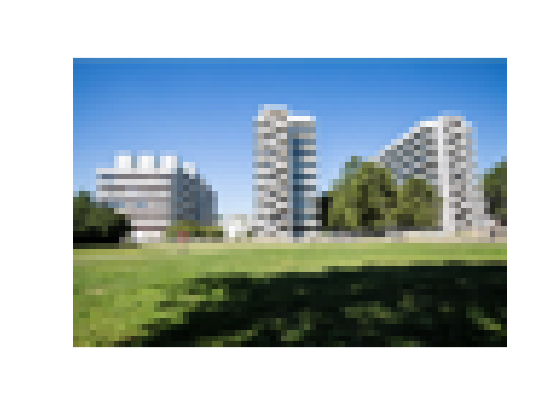

show_and_write(I, '../presentation/figures/kit-demo/image-resized.png');

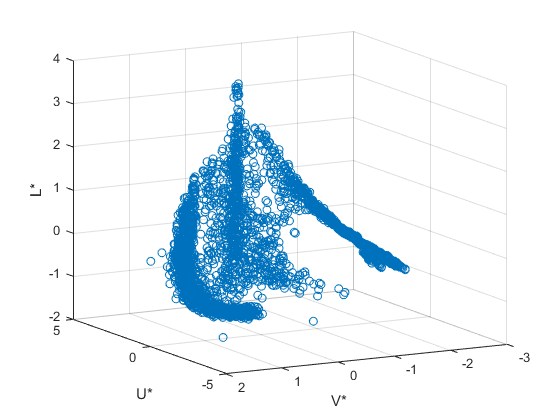

scatter3(X(1,:),X(2,:),X(3,:));
view([-118.58 13.52]);
xlabel('U*'); ylabel('V*'); zlabel('L*');
saveas(gcf, '../presentation/figures/kit-demo/scatter-plot.png');

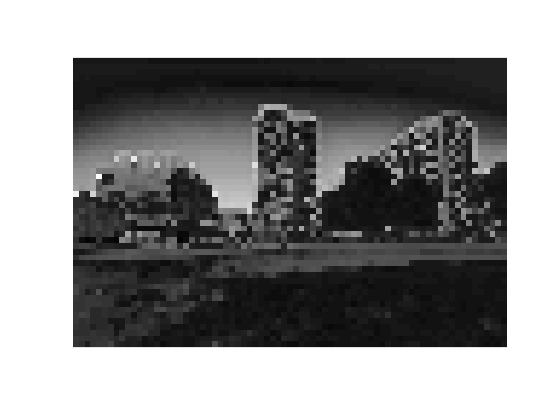

show_and_write(reshape(T, n_rows, n_cols) ./ max(T), image_path('image-iterations', kernel, bandwidth));

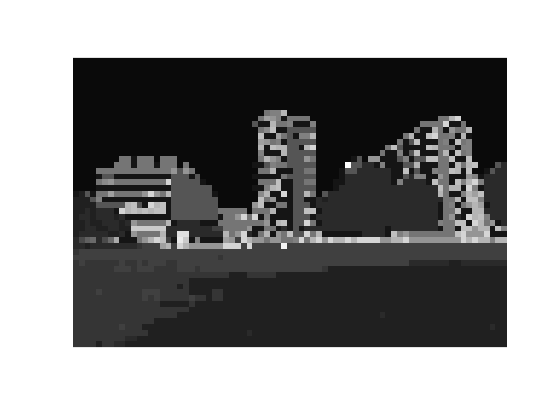

show_and_write(reshape(A, n_rows, n_cols) ./  max(A), image_path('image-clustering', kernel, bandwidth));

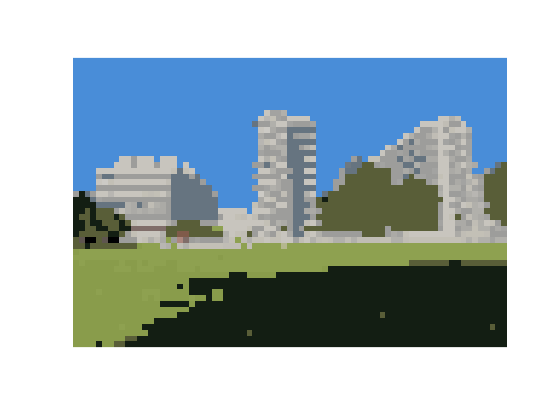

show_and_write(image_inverse_transform(C(:,A), n_rows, n_cols, m, s), image_path('image-segmentation', kernel, bandwidth));

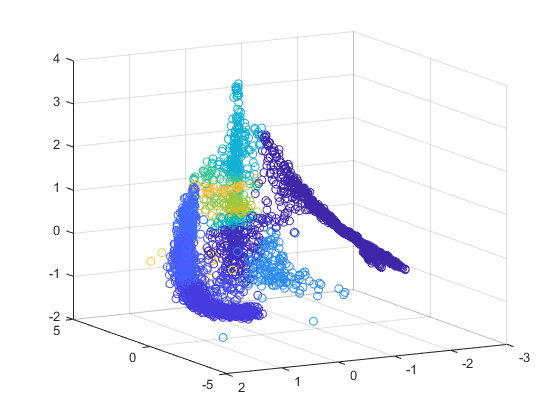

scatter3(X(1,:),X(2,:),X(3,:), [], A);
view([-118.58 13.52]);
xlabel('U*'); ylabel('V*'); zlabel('L*');
saveas(gcf, image_path('scatter-plot', kernel, bandwidth));

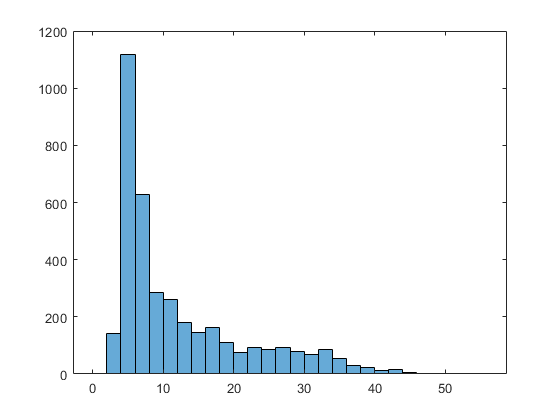

histogram(T)

function show_and_write(Image, ImagePath)
    figure
    imshow(Image, 'InitialMagnification', 'fit');
    imwrite(Image, ImagePath);
end

function path = image_path(name, kernel, bandwidth)
    path = strcat('../presentation/figures/kit-demo/',name,'-h=',num2str(bandwidth),'-K=',kernel,'.png');
end